Companion software for "Volker Ziemann, *Hands-on Accelerator physics using MATLAB, CRCPress, 2019*" (https://www.crcpress.com/9781138589940)

# One-to-one steering in a transfer line (Section 8.4.2)

Volker Ziemann, 211122, CC-BY-SA-4.0

In this example we illustrate the concept of one-to-one steering in a beam line with misaligned quadrupoles, where we use one corrector at a time to correct the orbit on the next BPM located downstream of the corrector.

To include the misaligned quadrupoles and steering magnets (=correctors), extern the `beamline` description with a fifth column, which includes the misalignment of the quads (elements with code 2) and also the excitation of the correctors (elements with code 100). We alos include beam position monitors (BPM) as elements having code 200. Here is the description of the `beamline`. We also need to update all the code to generate transfer matrices, which can be found below in the Appendix.

clear all
beamline=[
  1, 1, 0.5,   0, 0;
  2, 1,   0, 2.1, 2e-3;    % QF
  1, 1,   1,   0, 0;
100, 1,   0,   0, 0;       % COR1
  1, 1,   1,   0, 0;
200, 1    0,   0, 0;       % BPM1
  2, 1,   0,-2.1, -5.3e-3; % QD
  1, 1,   1,   0, 0;
100, 1,   0,   0, 0;       % COR2
  1, 1,   1,   0, 0;
200, 1    0,   0, 0;       % BPM2
  2, 1,   0, 2.1, 4e-3;    % QF
  1, 1,   1,   0, 0;
100, 1,   0,   0, 0;       % COR3
  1, 1,   1,   0, 0;
  2, 1,   0, 2.1,-3e-3;    % QD
  1, 1,   1,   0, 0; 
200, 1    0,   0, 0;       % BPM3
];

Note that the beamline describes a simple FODO lattice with alternating focusing and defocusing quads. Interspersed we just placed the steering magnets and the BPM. Note that the fifith column of the quadrupoles already contains non-zero entries, which accounts for a initial transverse misalignment. 

Occasionally it is useful to generate new quadrupole misalignments, which is accomplished by selecting the checkbox. But only do this once you've corrected the as-found configuration.

new_quad_misalignment=false;
if new_quad_misalignment
  dx=4e-3*randn(4,1);
  beamline(2,5)=dx(1);
  beamline(7,5)=dx(2);
  beamline(12,5)=dx(3);
  beamline(16,5)=dx(4);
end

The three sliders control the angle with which the steering magnets kick the beam. Note how the sliders just change the entry in the fifth column of the beamline, where the kick angle of the correctors is found.

beamline(4,5)=0;  % slider for COR1
beamline(9,5)=0;  % slider for COR2
beamline(14,5)=0;  % slider for COR3

Once we have all misalignments and corrector excitations defined, we can update all transfermatrices with `calcmat()`, allocate the lattice and launch a particle which is initially located on central axis, as indicated by the two zeros. The '1' in the third row is discussed in the Appendix. As the particle propagates through the beamline its transverse position `x(1)` is converted to mm and stored in the array `data()` for later display.

[Racc,spos,nmat,nlines]=calcmat(beamline);
data=zeros(nmat,1);    % allocate memory
x0=[0;0;1];
for k=1:nmat
  x=Racc(:,:,k)*x0;
  data(k)=1e3*x(1);   % convert to mm
end

The BPMs are located at position 6, 11, and 18 in the beamline, but there is one additional entry at s=0, such that all indices are increase by one, when we display the detected position in a bargraph, just as in a real control room. In the lower subplot, we display the trajectory that the beam takes through the beam line. Note that the  position of the steering magnets is indicated by a short red verical line and that of the BPMs by a longer blue line.

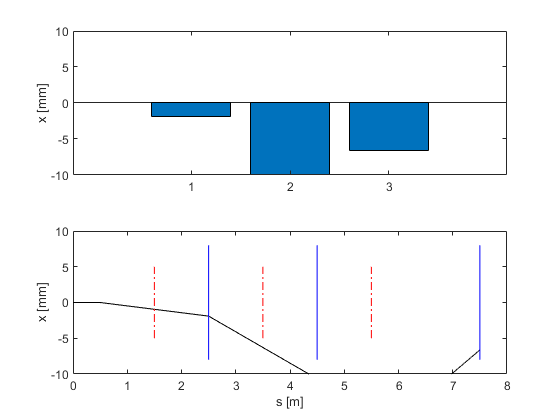

subplot(2,1,1); bar([data(7),data(12),data(19)]);
ylim([-10,10]); ylabel('x [mm]')
subplot(2,1,2); plot(spos,data,'k', ...
  [2.5,2.5],[-8,8],'b',[4.5,4.5],[-8,8],'b',[7.5,7.5],[-8,8],'b', ...
  [1.5,1.5],[-5,5],'r-.',[3.5,3.5],[-5,5],'r-.',[5.5,5.5],[-5,5],'r-.');
ylim([-10,10]); xlabel('s [m]'); ylabel('x [mm]') 

We suggest to do as discussed in Section 8.4.2 and use the first corrector to center the beam in the first BPM, then use the second corrector to center in the second BPM, and then continue in the same fashion. Once you have succeeded in centering the beam's position on all BPM to less than 1 mm, note how the 'real' trajectory, shown on the lower panel, still deviates from the center line; it just crosses the center line where the BPMs are located.

## Appendix

In order to keep track of the misaligned quadrupoles and the excitation of the steering magnets, we extend the 2x2 matrices to 3x3 matrices, because in this way we can include kicks intothe transfer matrix. Basically we rewrite

                                $\vec x_1 = \vec q + R\vec x_0$           as         $\left( \begin{array}{c} \vec_x_1\\ 1\end{array}\right) = 
\left( \begin{array}{cc} R & \vec q\\ 0 & 1 \end{array}\right)
\left( \begin{array}{c} \vec_x_0\\ 1\end{array}\right)  $

which also explains the '1' in the third row of the state vector. It is needed to pick up the third column in the transfer matrix. Applied to our system, we therefore place the kick from the misaligned thin quadrupole, which, according to Equation 8.2, is $-d_x/f$, into the third column of the transfer matrix. Likewise the place the kick from the steerer into the third column. The rest of the code remains unchanged compared to the version in the 2D subdirectory.

function [Racc,spos,nmat,nlines]=calcmat(beamline)
nlines=size(beamline,1);
nmat=sum(beamline(:,2))+1;
Racc=zeros(3,3,nmat);
Racc(:,:,1)=eye(3);
spos=zeros(nmat,1);
ic=1;
for line=1:nlines
  for seg=1:beamline(line,2)
    ic=ic+1;
    Rcurr=eye(3);
    switch beamline(line,1)
      case 1    % drift space
        Rcurr=DD(beamline(line,3));
      case 2    % quadrupole
        Rcurr=Q(beamline(line,4));
        Rcurr(2,3)=-beamline(line,5)/beamline(line,4);  % -dx/f
      case 100  % steering magnet              
        Rcurr(2,3)=beamline(line,5);                    % steerer kick
      case 200  % BPM
        Rcurr=eye(3);
      otherwise
        disp('unknown element');
    end
    Racc(:,:,ic)=Rcurr*Racc(:,:,ic-1);
    spos(ic)=spos(ic-1)+beamline(line,3);    
  end
end
end

#### DD(L)

The function `DD()` returns the 3x3 transfer matrix of a driftspace with length `L.`

function out=DD(L)
out=[1,L,0;0,1,0;0,0,1];
end

#### Q(F)

The function `Q()` returns the 3x3 transfer matrix of a thin quadrupole with focal length `F.`

function out=Q(F)
out=eye(3);
if abs(F)<1e-8, return; end
out(2,1)=-1/F;
end